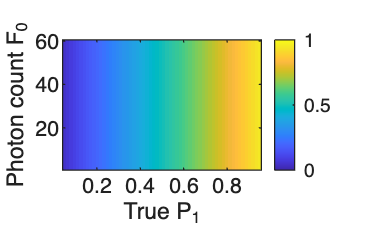

% Space out points on the x-axis 
% Starting from 12.5 up to 256.
t = linspace(12.5/256, 12.5, 256)';

% Decays are biologically fixed
tau1 = 2.14; 
tau2 = 0.69;

% Compute the column vectors of the A matrix 
a1 = exp(-t / tau1);
a2 = exp(-t / tau2);

% IRF centered at 2ns
mu = 2;

% Full with half max = 340ps (defining Gaussian for IRF)
fwhm = 0.34;

% Convert FWHM to standard deviation using known formula
% FWHM = 2 * sigma * sqrt{2 ln(2)}
sigma = fwhm / (2*sqrt(2*log(2)));

% Define IRF using Gaussian standard deviation formula
% Evenly space points
irf = exp(-(t - mu).^2 / (2*sigma^2));
irf = irf / sum(irf);

% Apply convolution to each vector of A
% 'Same' ==> we get col vector of length 256
a1_conv = conv(a1, irf, 'same');
a2_conv = conv(a2, irf, 'same');

% A matrix
A = [a1_conv, a2_conv];


%A = [a1,a2];

% % Number of photons (F_sensor)
% F_0 = 300000;
% 
% % Ground truth P1 value
% p1_real = 0.45;
% p2_real = 1-p1_real;


p1_vec = linspace(0.05, 0.95, 60);   % x-axis: true P1
F0_vec = logspace(3, 6, 60);         % y-axis: photon count
P1hat_grid = zeros(numel(F0_vec), numel(p1_vec));


for i = 1:numel(F0_vec)
    F_0 = F0_vec(i);
    for j = 1:numel(p1_vec)
        p1_real = p1_vec(j);
        p2_real = 1-p1_real;


        % Components of C matrix
        c1 = F_0*p1_real;
        c2 = F_0*p2_real;
        
        
        % Composed of F0P1 and F0P2
        c = [c1,c2]';
        
        % Gives: Measured Vals = F0P1e^{-t/tau1}+F0P2e^{-t/tau2}
        y = A * c;
        
        % Pseudoinverse * y = Fitted F0P1 and F0P2
        c_hat =(inv(A' * A)*A')*y;
        
        % Compute fitted values
        c1_hat = c_hat(1);
        c2_hat = c_hat(2);
        P1_hat = c1_hat / (c1_hat + c2_hat);
        
        P1hat_grid(i,j) = P1_hat;
    end
end

imagesc(p1_vec, 1:numel(F0_vec), P1hat_grid);
set(gca,'YDir','normal'); clim([0 1]); colorbar;
xlabel('True P_1'); ylabel('Photon count F_0');

bias = P1hat_grid - repmat(p1_vec, numel(F0_vec), 1);
fprintf('Max |bias|: %.3e\n', max(abs(bias(:))));

Max |bias|: 7.516e-14
